# Correction devoir #1

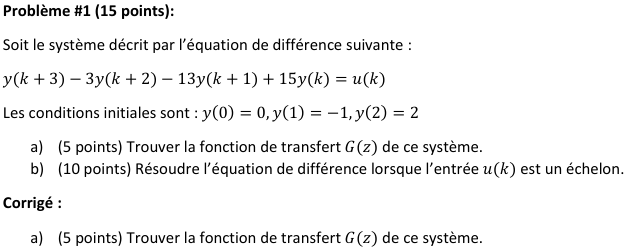

clc; clear;
syms z Z
% Fonction de transfert Gz - Conditions initiales nulles
yn0=0;
yn1=0;
yn2=0;
yn3=z^3*Z-z^3*yn0-z^2*yn1-z*yn2;
yn2=z^2*Z-z^2*yn0-z*yn1;
yn1=z*Z-z*yn0;
Gz=simplify(Z/(yn3-3*yn2-13*yn1+15*Z))

$$Gz = -\frac{1}{-z^{3}+3\,z^{2}+13\,z-15}$$

b) (10 points) Résoudre l’équation de différence lorsque l’entrée 𝑢(𝑘) est un échelon.

% Calcul de Y(z) - Conditions initiales non nulles
yn0=0;
yn1=-1;
yn2=2;
Yz=solve(yn3-3*yn2-13*yn1+15*Z==z/(z-1),Z)

$$Yz = \frac{\frac{z}{z-1}-7}{z^{3}+15}$$

% Calcul de y(k)
yn=iztrans(Yz)

$$yn = \frac{1}{16}-\frac{7\,\delta_{n,0}}{15}-\left(\sum_{r_{3}\in \mathrm{root}\left({z_{1}}^{3}+15,z_{1}\right)}\left(-\frac{r_{3}\,{r_{3}}^{n}}{720}-\frac{97\,{r_{3}}^{n}}{720}-\frac{{r_{3}}^{n}\,{r_{3}}^{2}}{720}\right)\right)$$

% Solution
Gz

$$Gz = -\frac{1}{-z^{3}+3\,z^{2}+13\,z-15}$$

Yz

$$Yz = \frac{\frac{z}{z-1}-7}{z^{3}+15}$$

yn

$$yn = \frac{1}{16}-\frac{7\,\delta_{n,0}}{15}-\left(\sum_{r_{3}\in \mathrm{root}\left({z_{1}}^{3}+15,z_{1}\right)}\left(-\frac{r_{3}\,{r_{3}}^{n}}{720}-\frac{97\,{r_{3}}^{n}}{720}-\frac{{r_{3}}^{n}\,{r_{3}}^{2}}{720}\right)\right)$$

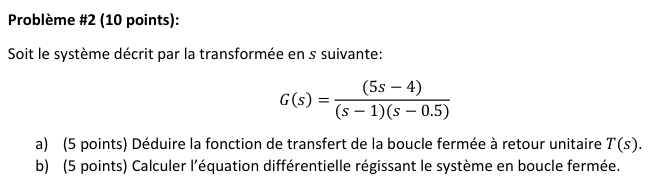

a) (5 points) Déduire la fonction de transfert de la boucle fermée à retour unitaire 𝑇(𝑠).

clc; clear;
syms s Ys U
Gs=(5*s-4)/((s-1)*(s-0.5));
% Boucle fermée
T=simplify(Gs/(1+Gs))

$$T = \frac{10\,s-8}{2\,s^{2}+7\,s-7}$$

b) (5 points) Calculer l’équation différentielle régissant le système en boucle fermée

% Équation différentielle
Y=(10*s-8)*U

$$Y = U\,\left(10\,s-8\right)$$

expand((2*s^2 + 7*s - 7)*Y==(10*s-8)*U)

$$ans = 20\,U\,s^{3}+54\,U\,s^{2}-126\,U\,s+56\,U=10\,U\,s-8\,U$$

% Solution
% T = (10*s - 8)/(2*s^2 + 7*s - 7)
% 2*ydot2 + 7*ydot - 7*y = 10*udot - 8*u

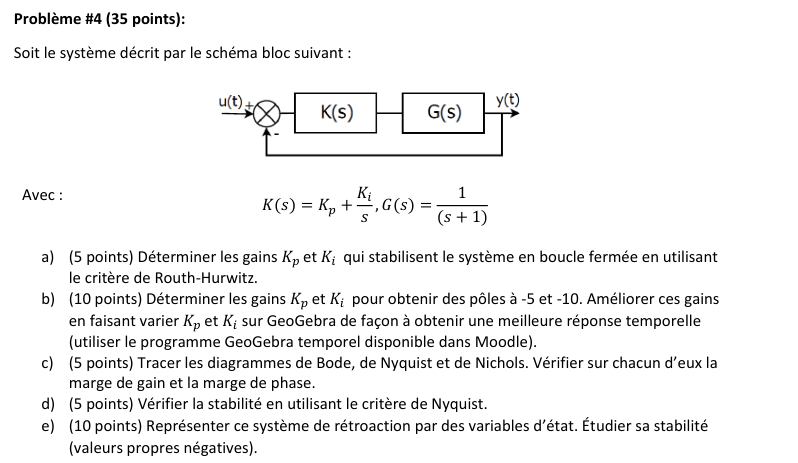

b) (10 points) Déterminer les gains 𝐾𝑝 et 𝐾𝑖 pour obtenir des pôles à -5 et -10. Améliorer ces gains

en faisant varier 𝐾𝑝 et 𝐾𝑖 sur GeoGebra de façon à obtenir une meilleure réponse temporelle.

Pour obtenir des pôles à -5 et -10 :

syms Kp Ki s t
P=1/(s+1);
C=Kp+(Ki/s);
L=P*C;
T=L/(1+L);
U=1/s;
Y=T*U;
y(t,Kp,Ki)=ilaplace(Y)

$$y(t, Kp, Ki) = 1-{\mathrm{e}}^{-t\,\left(\frac{\mathrm{Kp}}{2}+\frac{1}{2}\right)}\,\left(\cosh\left(t\,\sqrt{\frac{{\mathrm{Kp}}^{2}}{4}+\frac{\mathrm{Kp}}{2}-\mathrm{Ki}+\frac{1}{4}}\right)-\frac{\sinh\left(t\,\sqrt{\frac{{\mathrm{Kp}}^{2}}{4}+\frac{\mathrm{Kp}}{2}-\mathrm{Ki}+\frac{1}{4}}\right)\,\left(\frac{\mathrm{Kp}}{2}-\frac{1}{2}\right)}{\sqrt{\frac{{\mathrm{Kp}}^{2}}{4}+\frac{\mathrm{Kp}}{2}-\mathrm{Ki}+\frac{1}{4}}}\right)$$

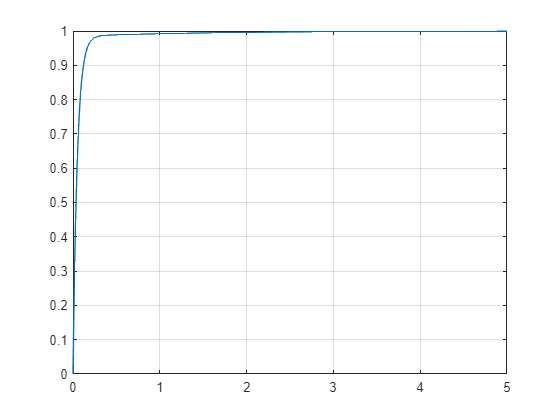

Kp=20;Ki=14;t=0:0.01:5;
%y=1 - exp(-t.*(Kp/2 + 1/2)).*(cosh((t.*(Kp^2 + 2.*Kp - 4.*Ki + 1)^(1/2))/2) - (2.*sinh((t.*(Kp^2 + 2.*Kp - 4.*Ki + 1)^(1/2))/2).*(Kp/2 - 1/2))/(Kp^2 + 2.*Kp - 4.*Ki + 1)^(1/2))
y(t,Kp,Ki);
figure
plot(t,y(t,Kp,Ki))
grid

c) (5 points) Tracer les diagrammes de Bode, de Nyquist et de Nichols. Vérifier sur chacun d’eux la

marge de gain et la marge de phase.

clc; clear;
syms ki kp s
KG=simplify((kp*s+ki)/(s*(s+1)));
T=simplify(KG/(1+KG));
expand((s+5)*(s+10));
% s^2 + 15*s + 50
% T = % (ki + kp*s)/(ki + s + kp*s + s^2)
kp=20;
ki=14;
s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



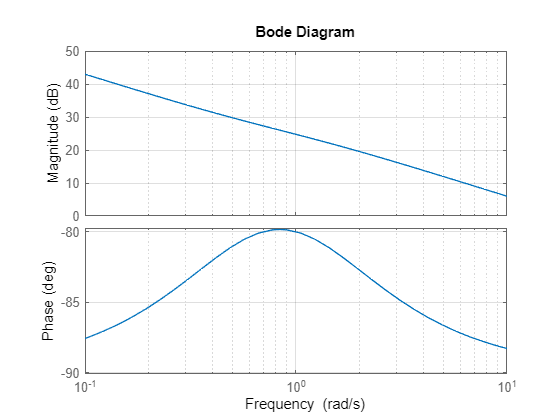

KG=simplify((kp*s+ki)/(s*(s+1)));
figure
bode(KG) ; grid;

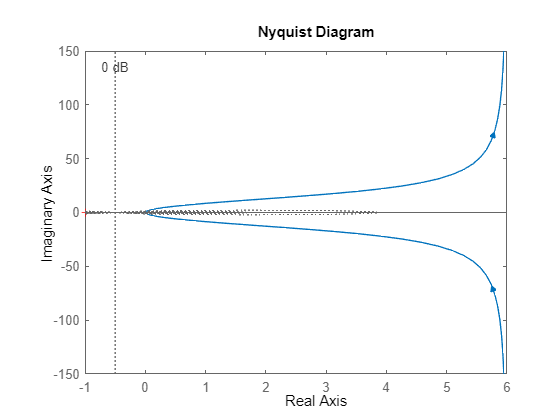

figure
nyquist(KG) ; grid;

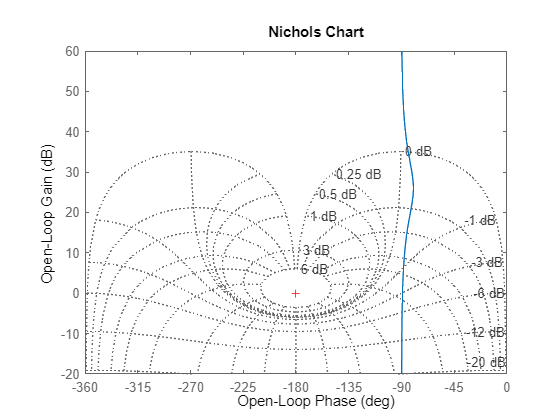

figure
nichols(KG) ; grid;

e) (10 points) Représenter ce système de rétroaction par des variables d’état. Étudier sa stabilité.

s=tf('s');
P=1/(s+1);
Kp=20;Ki=14;
C=Kp+(Ki/s);
L=P*C;
T=L/(1+L);
% T =
%
% 20 s^3 + 34 s^2 + 14 s
% ----------------------------
% s^4 + 22 s^3 + 35 s^2 + 14 s
[A,B,C,D]=tf2ss([20 34 14 0],[1 22 35 14 0])

A =    -22   -35   -14     0
     1     0     0     0
     0     1     0     0
     0     0     1     0


B =      1
     0
     0
     0


C =     20    34    14     0


D = 0

eig(A)

ans =          0
  -20.3107
   -1.0000
   -0.6893


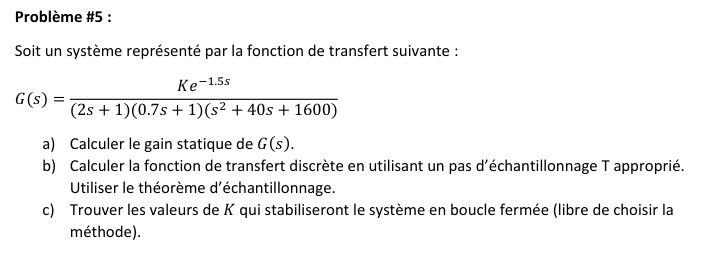

b) Calculer la fonction de transfert discrète en utilisant un pas d’échantillonnage T approprié.

Utiliser le théorème d’échantillonnage.

syms s
solve(s^2+40*s+1600==0,s);
% ans =
% - 20 - 3^(1/2)*20i
% - 20 + 3^(1/2)*20i
expand((2*s+1)*(0.7*s+1)*(s^2+40*s+1600));
% ans =
% (7*s^4)/5 + (587*s^3)/10 + 2349*s^2 + 4360*s + 1600
Gdelay = tf([1], [7/5 587/10 2349 4360 1600], 'InputDelay', 1.5);
% G =
% 1
% exp(-1.5*s) * ---------------------------------------------
% 1.4 s^4 + 58.7 s^3 + 2349 s^2 + 4360 s + 1600
T=1.5;
%Gz=c2d(G,T)
% Gz =
% 0.000206 z^3 + 8.507e-05 z^2 - 7.745e-10 z - 1.705e-21
% z^(-1) * --------------------------------------------------------
% z^4 - 0.5897 z^3 + 0.05542 z^2 + 1.293e-15 z + 4.852e-28

c) Trouver les valeurs de 𝐾 qui stabiliseront le système en boucle fermée (libre de choisir la

méthode).

figure
%rlocus(Gz)